% Clear workspace and initialize
clear all;
close all;


Question 01.


%% Question 01(a): y' + 2y = ex; y(0) = 1
disp("Question 01(a)");

Question 01(a)


syms x y;
equation_1_a = "Dy + 2*y = exp(x)";
equation_1_a

equation_1_a = "Dy + 2*y = exp(x)"

condition_1_a = "y(0) = 1";
condition_1_a

condition_1_a = "y(0) = 1"


% Solve for general and particular solutions
general_1_a = dsolve(equation_1_a, 'x');

general_1_a

$$general\_1\_a = \frac{{\mathrm{e}}^{x}}{3}+C_{1}\,{\mathrm{e}}^{-2\,x}$$

particular_1_a = dsolve(equation_1_a, condition_1_a, 'x');

particular_1_a

$$particular\_1\_a = \frac{2\,{\mathrm{e}}^{-2\,x}}{3}+\frac{{\mathrm{e}}^{x}}{3}$$

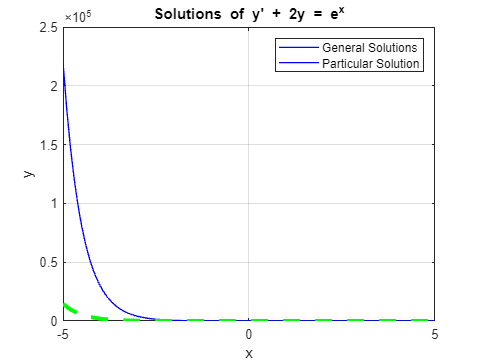


% Create figure for question 1(a)
figure('Name', 'Question 1(a) Solutions');
x = linspace(-5, 5, 100);
C1 = 10;

% Plot general solutions
for C = -3:0.5:3
    f1a = eval(vectorize(subs(general_1_a)));
    plot(x, f1a, 'b-', 'LineWidth', 1);
    hold on;
end

% Plot particular solution
f1a_particular = eval(vectorize(particular_1_a));
plot(x, f1a_particular, 'g--', 'LineWidth', 3);
grid on;
title('Solutions of y'' + 2y = e^x');
xlabel('x');
ylabel('y');
legend('General Solutions', 'Particular Solution');
hold off;


%% Question 01(b): y'' - 2y' + 10y = 10x^2 + 18x + 6; y(0) = 1, y'(0) = 3.2
disp("Question 01(b)");

Question 01(b)


equation_1_b = "D2y - 2*Dy + 10*y = 10*x^2 + 18*x + 6";
equation_1_b

equation_1_b = "D2y - 2*Dy + 10*y = 10*x^2 + 18*x + 6"

condition_1_b = "y(0) = 1, Dy(0) = 3.2";
condition_1_b

condition_1_b = "y(0) = 1, Dy(0) = 3.2"


% Solve for general and particular solutions
general_1_b = dsolve(equation_1_b, 'x');

general_1_b

$$general\_1\_b = \frac{11\,x}{5}+x^{2}+C_{1}\,\cos\left(3\,x\right)\,{\mathrm{e}}^{x}-C_{2}\,\sin\left(3\,x\right)\,{\mathrm{e}}^{x}+\frac{21}{25}$$

particular_1_b = dsolve(equation_1_b, condition_1_b, 'x');

particular_1_b

$$particular\_1\_b = \frac{11\,x}{5}+\frac{4\,\cos\left(3\,x\right)\,{\mathrm{e}}^{x}}{25}+\frac{7\,\sin\left(3\,x\right)\,{\mathrm{e}}^{x}}{25}+x^{2}+\frac{21}{25}$$

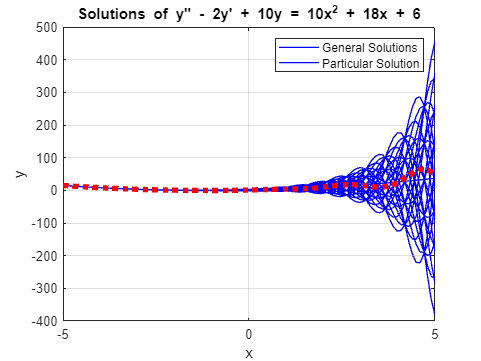


% Create figure for question 1(b)
figure('Name', 'Question 1(b) Solutions');
x = linspace(-5, 5, 100);

% Plot general solutions
for C1 = -2:1:2
    for C2 = -2:1:2
        f1b = eval(vectorize(subs(general_1_b)));
        plot(x, f1b, 'b-', 'LineWidth', 1);
        hold on;
    end
end

% Plot particular solution
f1b_particular = eval(vectorize(particular_1_b));
plot(x, f1b_particular, 'r:', 'LineWidth', 4);
grid on;
title('Solutions of y'''' - 2y'' + 10y = 10x^2 + 18x + 6');
xlabel('x');
ylabel('y');
legend('General Solutions', 'Particular Solution');
hold off;

Question 02.


%% Question 02: y''' + 2y'' + y' + 2e^(-2x) = 0
disp("Question 02");

Question 02



% Get number of solutions from user with default value of 5
n = input('Enter the number of solutions to plot (n) [Default=5]: ');
if isempty(n)  % If user just presses Enter
    n = 5;     % Use default value
end

% Get constant value with default value of 1
constant_val = input('Enter a constant value to use as base [Default=1]: ');
if isempty(constant_val)
    constant_val = 1;
end

% Define symbolic variables
syms y(x);
Dy = diff(y, x);
D2y = diff(y, x, 2);
D3y = diff(y, x, 3);

% Define and solve the ODE
equation_2 = D3y + 2*D2y + Dy + 2*exp(-2*x) == 0;
equation_2

$$equation\_2(x) = \frac{\partial^{3}}{\partial x^{3}}y\left(x\right)+2\,\frac{\partial^{2}}{\partial x^{2}}y\left(x\right)+\frac{\partial }{\partial x}y\left(x\right)+2\,{\mathrm{e}}^{-2\,x}=0$$

general_2 = dsolve(equation_2);
general_2

$$general\_2 = {\mathrm{e}}^{-2\,x}\,\left(x-C_{1}\,{\mathrm{e}}^{2\,x}+C_{1}\,x\,{\mathrm{e}}^{2\,x}+1\right)+C_{2}\,{\mathrm{e}}^{-x}-x\,{\mathrm{e}}^{-x}\,\left({\mathrm{e}}^{-x}+C_{1}\,{\mathrm{e}}^{x}\right)+C_{3}\,x\,{\mathrm{e}}^{-x}$$


% Example particular solution
particular_2_example = subs(general_2, 'C1', 1);
particular_2_example

$$particular\_2\_example = {\mathrm{e}}^{-2\,x}\,\left(x-{\mathrm{e}}^{2\,x}+x\,{\mathrm{e}}^{2\,x}+1\right)+C_{2}\,{\mathrm{e}}^{-x}+C_{3}\,x\,{\mathrm{e}}^{-x}-x\,{\mathrm{e}}^{-x}\,\left({\mathrm{e}}^{-x}+{\mathrm{e}}^{x}\right)$$

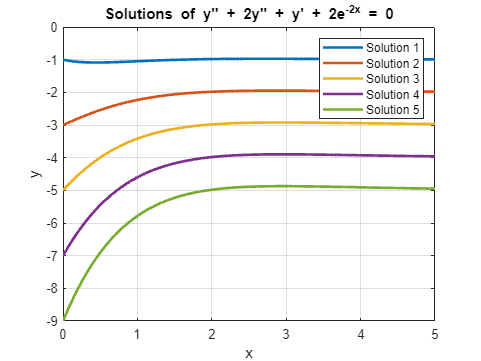


% Create figure
figure('Name', 'Question 2 Solutions');
x = linspace(0, 5, 100);

% Plot n particular solutions with different initial conditions
for i = 1:n
    % Use different multiples of the constant value for each solution
    sol = subs(general_2, {'C1', 'C2', 'C3'}, ...
               {constant_val*i, constant_val*(-i), constant_val*(i/2)});
    y_vals = double(subs(sol, x));
    plot(x, y_vals, 'LineWidth', 2);
    hold on;
end

grid on;
title('Solutions of y'''' + 2y'''' + y'' + 2e^{-2x} = 0');
xlabel('x');
ylabel('y');

% Create legend entries based on number of solutions
legend_entries = cell(1,n);
for i = 1:n
    legend_entries{i} = ['Solution ' num2str(i)];
end
legend(legend_entries);
hold off;

Question 03.


%% Question 03: System of ODEs
disp("Question 03");

Question 03



% x' = 3x + 4y
% y' = 2x + y

% Define symbolic variables
syms x(t) y(t)

% Define the system of ODEs
eq1 = diff(x) == 3*x + 4*y;
eq1

$$eq1(t) = \frac{\partial }{\partial t}x\left(t\right)=3\,x\left(t\right)+4\,y\left(t\right)$$

eq2 = diff(y) == 2*x + y;
eq2

$$eq2(t) = \frac{\partial }{\partial t}y\left(t\right)=2\,x\left(t\right)+y\left(t\right)$$


% Solve the system using dsolve
[x_sol, y_sol] = dsolve(eq1, eq2);

% Display the general solutions
disp('x(t) = ');

x(t) = 


pretty(x_sol)

C2 exp(5 t) 2 - C1 exp(-t)



disp('y(t) = ');

y(t) = 


pretty(y_sol)

C1 exp(-t) + C2 exp(5 t)



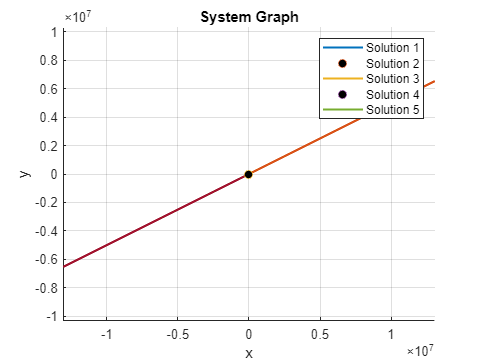


% Create a plot to visualize different particular solutions
figure('Name', 'System Graph')

% Define time range for solutions
t = linspace(0, 3, 100);

% We'll plot 5 different particular solutions with different initial conditions
initial_conditions = [
    [1, 0];    % First set 
    [0, 1];    % Second set
    [-1, -1];  % Third set
    [2, -2];   % Fourth set
    [-2, 2]    % Fifth set
];

% Plot each particular solution
hold on
for i = 1:5
    % Substitute initial conditions
    x0 = initial_conditions(i,1);
    y0 = initial_conditions(i,2);
    
    % Create particular solutions by substituting constants
    x_particular = subs(x_sol, {'C1', 'C2'}, {x0, y0});
    y_particular = subs(y_sol, {'C1', 'C2'}, {x0, y0});
    
    % Convert to numerical values
    x_values = double(subs(x_particular, 't', t));
    y_values = double(subs(y_particular, 't', t));
    
    % Plot the solution trajectory
    plot(x_values, y_values, 'LineWidth', 1.5)
    
    % Plot starting point
    plot(x0, y0, 'o', 'MarkerFaceColor', 'black')
end

% Add direction field (quiver plot)
[X, Y] = meshgrid(-3:0.5:3, -3:0.5:3);
dX = 3*X + 4*Y;
dY = 2*X + Y;

% Normalize vectors for better visualization
norm = sqrt(dX.^2 + dY.^2);
quiver(X, Y, dX./norm, dY./norm, 0.3, 'Color', [0.7 0.7 0.7])

% Customize the plot
grid on
xlabel('x')
ylabel('y')
title('System Graph')
axis equal
legend('Solution 1', 'Solution 2', 'Solution 3', 'Solution 4', 'Solution 5')
hold off